# Разностный метод решения краевой задачи для обыкновенного дифференциального уравнения второго порядка. Метод прогонки. Вариант 11.

## Комментарий к задаче

Требуется получить численное решение следующей краевой задачи:


$$-\frac{7-x}{8+3x} u'' + \left(1+\frac{x}{3}\right)u' +\left(1-\frac{1}{2} e^{\frac{x}{2}}\right) u = \frac{1}{2} - \frac{x}{3},\ u(-1)=u(1)=0$$


Заметим, что в граничных условиях $|\alpha_2|+|\beta_2| = 0 \Longrightarrow$ суммарный порядок аппроксимации дифференциальной задачи разностной схемы второй уже на основной схеме. Поэтому все методы, описанные далее, реализованы на основной сетке и имеют порядок точности $O(h^2)$.

## Точное решение

Получим "точное" решение краевой задачи встроенными методами языка MATLAB. 

**Примечание: **см. acc_solution.m 

Y_ex = acc_solution

Y_ex =          0    0.0384    0.0733    0.1049    0.1330    0.1579    0.1796    0.1979    0.2130    0.2248    0.2330    0.2377    0.2384    0.2348    0.2263    0.2121    0.1911    0.1619    0.1224    0.0698   -0.0000


## Алгоритм

### Аппроксимация дифференциального уравнения разностными

Дано дифференциальное уравнение второго порядка


$$-p(x) u'' +q(x)u' +r(x) u = f(x)$$


Пусть $p_i = (p(x_i)),\ q_i = (q(x_i)),\ r_i = (r(x_i)),\ f_i = (f(x_i)) $. Заменим производные конечно-разностными отношениями, получим


$$-p_i\frac{y_{i+1} - 2y_i + y_{i-1}}{h^2} + q_i \frac{y_{i+1}-y_{i-1}}{2h} + r_i = f_i,\ i=1,\dots,n-1$$


Перегруппируем коеффициенты при $y_i$, получим

$A_iy_{i-1} - B_iy_{i} + C_i y_{i+1} = G_i,\ i=1,\dots,n-1$, где $(1)
$

- 
$$A_i = -\left(\frac{p_i}{h^2}+\frac{q_i}{2h}\right)$$


- 
$$B_i = -\left(\frac{2p_i}{h^2} + r_i\right)$$


- 
$$C_i = \frac{q_i}{2h} - \frac{p_i}{h^2}$$


- 
$$G_i = f_i$$


### Аппроксимация граничных условий

Граничные условия имеют вид:

- 
$$\alpha_1 y(a)+ \alpha_2 y'(a)=\alpha$$


- 
$$\beta_1 y(b) + \beta_2 y'(b) = \beta$$


Пусть $y_0 = y(a),\ y_n = y(b)$. Заменим производные конечно-разностными отношениями, получим

- 
$$\alpha_1 y_0+ \alpha_2 \frac{y_{1} - y_{0}}{h}=\alpha$$


- 
$$\beta_1 y_n + \beta_2 \frac{y_n - y_{n-1}}{h} = \beta$$


Перегруппируем коеффициенты, получим

- 
$$-B_0 y_0 + C_0 y_1 = G_0$$


- 
$$A_n y_{n-1} - B_n y_{n} = G_n $$


Где $(2)$

- 
$$B_0 = \alpha_1 +\frac{\alpha_2}{h}, C_0 = -\frac{\alpha_2}{h} $$


- 
$$A_n = \beta_1 +\frac{\beta_2}{h}, B_n = -\frac{\beta_2}{h} $$


### Итог

Получаем следующую систему $(3)$:


$$\begin{cases} -B_0 y_0 + C_0y_1 = G_0  \\ \dots \\ A_i y_{i-1} - B_i y_{i} + C_i y_{i+1} = G_i\\ \dots\\ A_n y_{n-1} - B_n y_{n} = G_n \end{cases}$$


Решим ее методом прогонки:

1) Найдем коеффициенты $s_i, t_i $ по следующим формулам $(5)$:         

- 
$$s_0 = \frac{C_0}{B_0},\ t_0 = -\frac{G_0}{B_0}$$


- 
$$s_i = \frac{C_i}{B_i - A_i s_{i-1}},\ t_i = \frac{A_i t_{i-1} - G_i}{B_i - A_i s_{i-1}},\ i = 1,\dots,n$$


2) Найдем $y_i$ по следующим формулам $(6)$:

- 
$$y_n = t_n$$


- 
$$y_{i-1} = s_i y_{i+1} + t_i,\ i=0,\dots,n-1$$


## Решение с точностью O(h^2) при n = 10

### Определение сетки узлов

Определим сетку узлов.

n1 = 10;
a = -1;
b = 1;
h1 = (b-a)/n1;
x1=a:h1:b;

### Поиск коеффициентов

Найдем необходимые для решения задачи коеффициенты по формулам $(1)$ и $(2)$

**Комм: **реализация описана в функции coefficients.m

[A1,B1,C1,G1] = coefficients(a,b,h1)

A1 =          0  -36.6548  -32.6452  -29.3725  -26.6577  -24.3750  -22.4341  -20.7681  -19.3265  -18.0705         0


B1 =    -5.0000  -70.3077  -61.9199  -55.0024  -49.1962  -44.2500  -39.9823  -36.2589  -32.9781  -30.0618   -5.0000


C1 =          0  -32.9881  -28.6452  -25.0392  -21.9910  -19.3750  -17.1008  -15.1014  -13.3265  -11.7372         0


G1 =          0    0.7667    0.7000    0.6333    0.5667    0.5000    0.4333    0.3667    0.3000    0.2333         0


### Результат

Решим систему $(3)$ методом прогонки. 

**Комм. **алгоритм реализован в функции TMA_algorithm.m

[Y_n1,s1,t1] = TMA_algorithm(A1,B1,C1,G1);

Представим результаты в следующей таблице

table1 = table(transpose(x1),transpose(A1),transpose(B1),transpose(C1),transpose(G1),transpose(s1),transpose(t1),transpose(Y_n1));
table1.Properties.VariableNames = {'x_i','A_i','B_i','C_i','G_i','s_i','t_i','Y_i'}

table1 = 11×8 table
    x_i       A_i        B_i        C_i        G_i        s_i        t_i         Y_i   
    ____    _______    _______    _______    _______    _______    ________    ________

      -1          0         -5          0          0          0           0           0
    -0.8    -36.655    -70.308    -32.988    0.76667     0.4692    0.010904    0.073257
    -0.6    -32.645     -61.92    -28.645        0.7    0.61466    0.022659     0.13289
    -0.4    -29.373    -55.002    -25.039    0.63333    0.67769    0.035154     0.17934
    -0.2    -26.658    -49.196    -21.991    0.56667    0.70641    0.048306     0.21276
       0    -24.375     -44.25    -19.375        0.5    0.71676    0.062056      0.2328
   

## Решение с точностью O(h^2) при n = 20

### Результат

Повторим описанные выше шаги для нового значения n

n2 = 20;
h2 = (b-a)/n2;
x2=a:h2:b;
[A2,B2,C2,G2] = coefficients(a,b,h2);

Получим

Y_n2 = TMA_algorithm(A2,B2,C2,G2)

Y_n2 =          0    0.0384    0.0733    0.1048    0.1330    0.1579    0.1795    0.1979    0.2129    0.2247    0.2330    0.2376    0.2383    0.2347    0.2262    0.2121    0.1912    0.1620    0.1225    0.0699         0


### Уточнение по Ричардсону

Используя расчитанные ранее значения $Y_{n1} $ и $Y_{n2}$, найдем главный член погрешности по формуле:


$$R^{(h)}_m = \frac{y^{\left(\frac{h}{2}\right)}_m - y^{(h)}_m}{2^s-1}$$


R_n2 = (Y_n2(1:2:21) - Y_n1)/3;

Уточним значение в узлах сетки по формуле:


$$\hat y_m = y^{\left(\frac{h}{2}\right)}_m + R^{(h)}_m$$


Y_ut = Y_n2(1:2:21) + R_n2;

### Сравнение с точным значением

#### Таблица

Найдем разницу между точным и уточненным значениями

difference = Y_ut - Y_ex(1:2:21);

Результат оформим в виде таблицы

table2 = table(transpose(x1),transpose(Y_ex(1:2:21)),transpose(Y_ut),transpose(difference));
table2.Properties.VariableNames = {'x_i','Y_ex','Y_ut','Y_ut - Y_ex'}

table2 = 11×4 table
    x_i        Y_ex          Y_ut      Y_ut - Y_ex
    ____    ___________    ________    ___________

      -1              0           0             0 
    -0.8       0.073338    0.073339    5.2204e-07 
    -0.6        0.13305     0.13305     1.047e-06 
    -0.4        0.17955     0.17956    1.6191e-06 
    -0.2        0.21301     0.21301    2.2387e-06 
       0        0.23304     0.23304    2.9204e-06 
     0.2        0.23839     0.23839    3.6426e-06 
     0.4        0.22625     0.22626    4.2802e-06 
     0.6        0.19112     0.19112    4.4447e-06 
     0.8        0.12244     0.12244    3.3378e-06 
       1    -5.3784e-20           0    5.3784e-20 


#### Графики

Построим графики "точного" и уточненного решения.

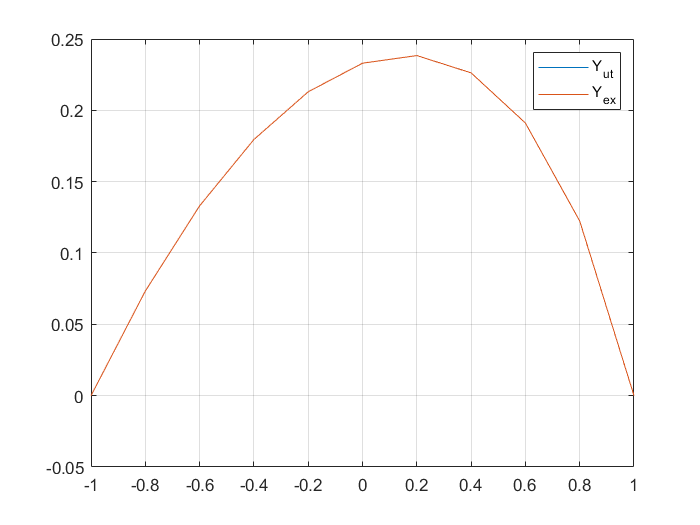

plot(x1,Y_ut)
hold on
plot(x1,Y_ex(1:2:21));
hold off
grid on
legend ('Y_{ut}','Y_{ex}')

При таком масштабе разница между значениями функций не заметна.

Рассмотрим окрестность точки $(0.2, 0,238385)$. 

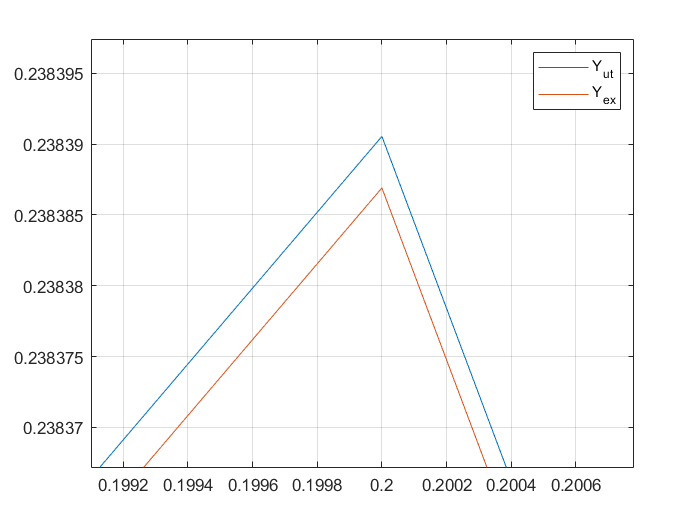

plot(x1,Y_ut)
hold on
plot(x1,Y_ex(1:2:21));
hold off
grid on
legend ('Y_{ut}','Y_{ex}')

xlim([0.19910 0.20078])
ylim([0.2383672 0.2383974])

На данном графике видно, что уточненное значение получилось немного больше "точного" значения.